%%Cama cu tachet
%1. Numarul de ordine i:
i=13

i = 13


%2. Numerele de dinti ale rotii dintate:
z1=34

z1 = 34

z2=42

z2 = 42


%3. Turatie motorului:
n1=(55+7*i)*10 %[rad/min]

n1 = 1460


%4. Turatia de iesire din reductor
n2=z1/z2*n1

n2 = 1.1819e+03


%5. Raport de transmitere
i1=z2/z1

i1 = 1.2353

i2=-z2/z1

i2 = -1.2353


%6. Inaltimea maxima
h=8+0.5*i

h = 14.5000


%7. Unghiul fazei la urcare
phiu=77+i;

%8. Unghiul fazei la coborare
phic=360-phiu-phiR-phir 

phic = 122


%9. Unghiul fazei repaus superior
phiR=80

phiR = 80


%10. Unghiul fazei repaus inferior
phir=68

phir = 68


%11. Unghiul de presiune
alpha=(45*pi)/180

alpha = 0.7854



%%Legile de miscare
phi=0:5:90

phi =      0     5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90


ku = pi/phiu

ku = 0.0349

C1u = -h/2

C1u = -7.2500

C2u = 0

C2u = 0

C3u = h/2

C3u = 7.2500


%Spatiul
Su = @(phi)(C1u*cos(ku*phi) + C2u*phi + C3u)

Su = function_handle with value:
    @(phi)(C1u*cos(ku*phi)+C2u*phi+C3u)


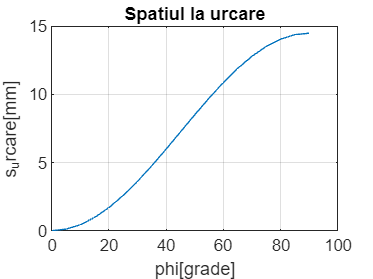

figure
plot(phi, Su(phi)), grid, title('Spatiul la urcare')
ylabel('s_urcare[mm]'), xlabel('phi[grade]')


%Viteza redusa
vu = @(phi)(-ku*C1u*sin(ku*phi)+C2u)

vu = function_handle with value:
    @(phi)(-ku*C1u*sin(ku*phi)+C2u)


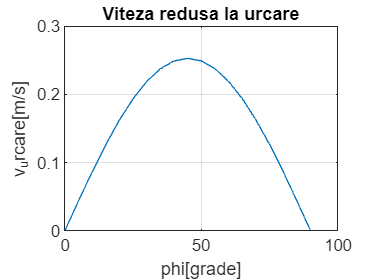

figure
plot(phi, vu(phi)), grid, title('Viteza redusa la urcare')
ylabel('v_urcare[m/s]'), xlabel('phi[grade]')


%Acceleratia redusa
au = @(phi)(-ku^2*C1u*cos(ku*phi))

au = function_handle with value:
    @(phi)(-ku^2*C1u*cos(ku*phi))


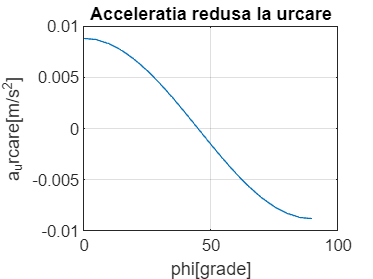

figure
plot(phi, au(phi)), grid, title('Acceleratia redusa la urcare')
ylabel('a_urcare[m/s^2]'), xlabel('phi[grade]')



%%La coborare
phi = 0:5:120

phi =      0     5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100   105   110   115   120


kc = 2*pi/phic

kc = 0.0515

C1c = h/(2*pi)

C1c = 2.3077

C2c = -h/phic

C2c = -0.1189

C3c = h

C3c = 14.5000


%Spatiul
Sc = @(phi)(C1c*sin(kc*phi) + C2c*phi + C3c)

Sc = function_handle with value:
    @(phi)(C1c*sin(kc*phi)+C2c*phi+C3c)


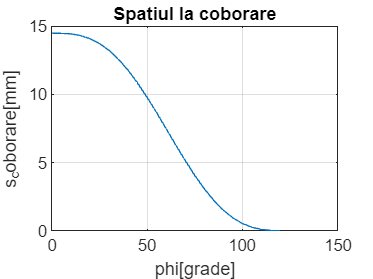

figure
plot(phi, Sc(phi)), grid, title('Spatiul la coborare')
ylabel('s_coborare[mm]'), xlabel('phi[grade]')


%Viteza redusa
vc = @(phi)(kc*C1c*cos(kc*phi)+C2c)

vc = function_handle with value:
    @(phi)(kc*C1c*cos(kc*phi)+C2c)


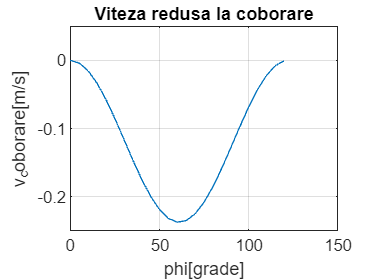

figure
plot(phi, vc(phi)), grid, title('Viteza redusa la coborare')
ylabel('v_coborare[m/s]'), xlabel('phi[grade]')


%Acceleratia redusa
ac = @(phi)(-kc^2*C1c*sin(kc*phi))

ac = function_handle with value:
    @(phi)(-kc^2*C1c*sin(kc*phi))


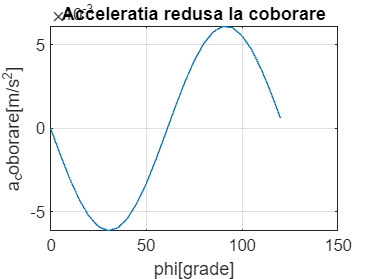

figure
plot(phi, ac(phi)), grid, title('Acceleratia redusa la coborare')
ylabel('a_coborare[m/s^2]'), xlabel('phi[grade]')